# Exam 2018

## 18.1

I = gray_run(6,6,[4, 100, 5, 90, 6, 50, 1, 200, 4, 140, 3, 210, 4, 70, 4, 17, 5, 5])

I =    100   100   100   100    90    90
    90    90    90    50    50    50
    50    50    50   200   140   140
   140   140   210   210   210    70
    70    70    70    17    17    17
    17     5     5     5     5     5


I1 = I>195

I1 = 6×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   1   0   0
   0   0   1   1   1   0
   0   0   0   0   0   0
   0   0   0   0   0   0


se = strel('disk',1);
I2 = imdilate(I1,se)

I2 = 6×6 logical array
   0   0   0   0   0   0
   0   0   0   1   0   0
   0   0   1   1   1   0
   0   1   1   1   1   1
   0   0   1   1   1   0
   0   0   0   0   0   0


sum(sum(I2))

ans = 12

## 18.2

rott = [4,2;3,5]

rott =      4     2
     3     5


p = [4;7]

p =      4
     7


r = rot(15)

r =     0.9659   -0.2588
    0.2588    0.9659


r*rott*p

ans =    16.8133
   53.1631


## 18.3

M = run_length(10,10,[2,2,3,4,5,6]+1,[1,5,3,4,4,4;2,6,3,4,4,4]+1)

M =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     1     1     0     0     1     1     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


I = bwlabel(M,8)

I =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     1     1     0     0     2     2     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


5/4

ans = 1.2500

## 18.4

2*tand(35/2)*20

ans = 12.6120

## 18.5

I = [193,180,20,112,125;
    189,8,177,97,114;
    100,71,16,195,165;
    167,12,242,203,181;
    44,25,9,48,192]

I =    193   180    20   112   125
   189     8   177    97   114
   100    71    16   195   165
   167    12   242   203   181
    44    25     9    48   192


II = remapping(I,30,220)

II =   180.2137  169.6581   39.7436  114.4444  125.0000
  176.9658   30.0000  167.2222  102.2650  116.0684
  104.7009   81.1538   36.4957  181.8376  157.4786
  159.1026   33.2479  220.0000  188.3333  170.4701
   59.2308   43.8034   30.8120   62.4786  179.4017


[A,T,P,cost] = findpath(II)

A =   180.2137  169.6581   39.7436  114.4444  125.0000
  346.6239   69.7436  206.9658  142.0085  230.5128
  174.4444  150.8974  106.2393  323.8462  299.4872
  310.0000  139.4872  326.2393  294.5726  469.9573
  198.7179  183.2906  170.2991  357.0513  473.9744


T =      0     0     0     0     0
     2     3     3     3     4
     2     2     2     4     4
     2     3     3     3     5
     2     2     2     4     4


P =      0     0     1     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     1     0     0     0
     0     0     1     0     0


cost = 170.2991

## 18.8

v = blinliner(121.6,237.2,[73,108,65,57])

v = 87.2400

## 18.9

r = [120,20,30;170,20,70;120,140,70]

r =    120    20    30
   170    20    70
   120   140    70


g = [40,150,20;20,110,20;25,20,20]

g =     40   150    20
    20   110    20
    25    20    20


b = [20,60,150;190,20,250;20,30,40]

b =     20    60   150
   190    20   250
    20    30    40


I = zeros(3,3,3);
I(:,:,1) = r;
I(:,:,2) = g;
I(:,:,3) = b;
s = zeros(3,1)

s =      0
     0
     0


1-6/23

ans = 0.7391

## 18.10

I = [140,102,106;37,19,13;0,0,0]

I =    140   102   106
    37    19    13
     0     0     0


M = ceil(((I./255).^1.16).*255)

M =    128    89    93
    28    13     9
     0     0     0


T = [-1,0,1;-2,0,2;-1,0,1]

T =     -1     0     1
    -2     0     2
    -1     0     1


sum(sum(M.*T))

ans = -73

## 18.11

I = run_length(15,15,[9,10,11,12],[5,3,2,4;5,6,6,6])

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     0     0     0     0     0     0     0     0     0


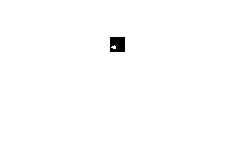

imshow(I)

se1 = strel('disk',1);
se2 = strel('square',3);
I1 = imdilate(I,se1)

I1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0


I2 = imerode(I1,se2)

I2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0


sum(sum(I2))

ans = 7

## 18.12

I = run_length(15,15,[4,5,6,6,7,8,8,9,9,10,10,11,11,11,12,12,12],[3,2,4,8,8,8,11,5,11,3,11,2,8,10,4,8,11;5,7,4,10,9,8,11,5,13,6,13,6,8,11,6,8,11])

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     1     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     1     1     1     0     0
     0     0     1     1     1     1     0     0     0     0     1     1     1     0     0


norm([16,5/9]-[12,0.75])

ans = 4.0047

norm([2,2]-[12,0.75])

ans = 10.0778

norm([13,4/5]-[12,0.75])

ans = 1.0012

norm([10,5/4]-[12,0.75])

ans = 2.0616

## 18.13

I1 = [120,20,30;170,20,70;120,140,70]

I1 =    120    20    30
   170    20    70
   120   140    70


I2 = [40,150,20;20,110,20;25,20,20]

I2 =     40   150    20
    20   110    20
    25    20    20


I3 = [20,60,150;190,20,250;20,30,40]

I3 =     20    60   150
   190    20   250
    20    30    40


I = I1*0.299+I2*0.587+I3*0.114

I =    61.6400  100.8700   37.8100
   84.2300   72.8300   61.1700
   52.8350   57.0200   37.2300


A = [238,180,81;173,8,242;193,71,9]

A =    238   180    81
   173     8   242
   193    71     9


sum(sum(A.*I))

ans = 8.0428e+04

## 18.14

corr = norm_corr(A,I)

corr = 0.8560

## 18.15

(1-0.9157)*76

ans = 6.4068

76/(76+7)

ans = 0.9157

## 18.16

m1 = mean([67,68,70])

m1 = 68.3333

m2 = mean([25,42,32])

m2 = 33

m3 = mean([81,76,72])

m3 = 76.3333

d1 = mean([m1,m2])

d1 = 50.6667

d2 = mean([m1,m3])

d2 = 72.3333

## 18.19

2000*2000*7/4200/150

ans = 44.4444

## 18.20

m = mean([24.2,253.7;43.2,301.3]')

m =   138.9500  172.2500


m = m';
[0.7,1;-3,0.4]*m

ans =   269.5150
 -347.9500


## 18.24

I = [177,195,181,30,192,140;81,203,192,127,65,35]

I =    177   195   181    30   192   140
    81   203   192   127    65    35


[A,T,P,cost] = findpath(I)

A =    177   195   181    30   192   140
   258   380   222   157    95   175


T =      0     0     0     0     0     0
     1     1     4     4     4     6


P =      0     0     0     1     0     0
     0     0     0     0     1     0


cost = 95